# **ECE 1473 OFDM Tutorial: **

# **Modulate Single Symbol of OFDM from Bits**

## **Author: Adam Nichols**

Welcome to an introduction on OFDM digital modulation!

This script will be a tutorial on how to use basic communications concepts and modules to generate a single symbol of OFDM.

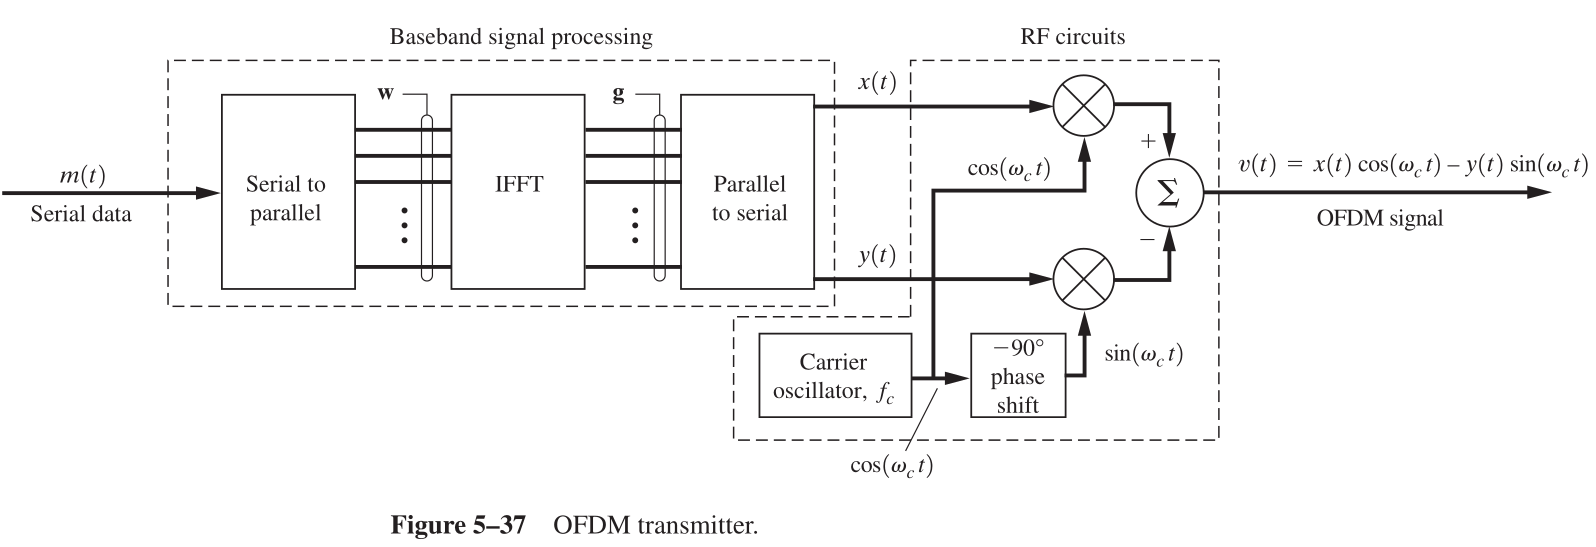

[1] Couch ADD REF

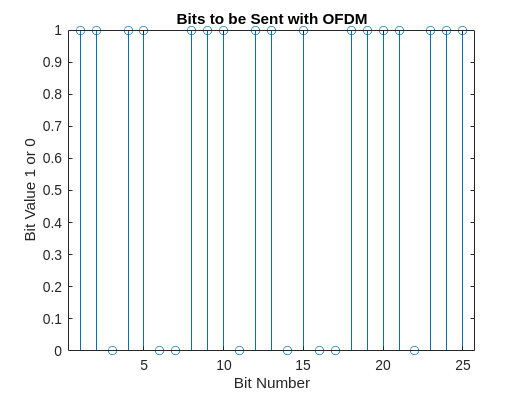

% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a single symbol of OFDM

% reset the workspace
clear, clc

%% generate random bits to be sent over the air

% initialize the variables that determine number of bits (assuming BPSK
% carriers)
num_carriers = 25;
num_bits = num_carriers;

% create a string of random bits to the required length
bits = zeros(num_bits,1);
for i = 1:num_bits
    bits(i) = randi(2,1)-1;
end

% create a stem plot to show the bits
figure(1)
clf
stem(1:num_bits, bits)
title("Bits to be Sent with OFDM")
xlabel("Bit Number")
ylabel("Bit Value 1 or 0")

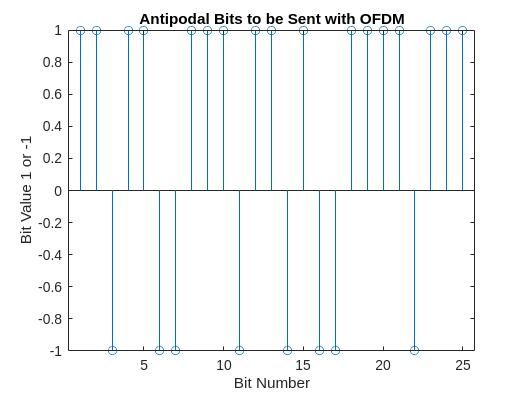


%% define modulation parameters
bitrate = 10000; % [bps]

%% build the vector of fourier coefficients to generate OFDM signal

% convert to antipodal bits (1 => 1, 0 => -1)
tx_bits = bits*2 - 1;
% create a stem plot to show the bits
figure(2)
clf
stem(1:num_bits, tx_bits)
title("Antipodal Bits to be Sent with OFDM")
xlabel("Bit Number")
ylabel("Bit Value 1 or -1")

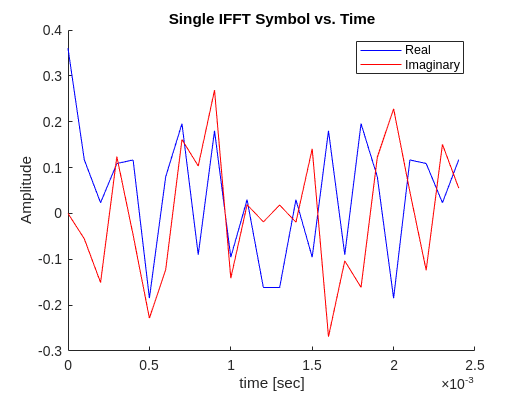


% the tx bits represent fourier coefficients, use ifft to get time domain
% message
s_t = ifft(tx_bits);

% generate the ifft time vector to represent proper frequency spacing and
% bitrate, and list parameters of the OFDM
OFDM_symbolrate = bitrate / num_carriers;
OFDM_symboltime = 1/OFDM_symbolrate;
OFDM_sampleperiod = OFDM_symboltime / num_carriers;
OFDM_samplerate = 1/OFDM_sampleperiod;
t = (0:num_bits-1)*OFDM_sampleperiod;

% plot the time domain message
figure(3)
clf
hold on
plot(t, real(s_t), 'b-')
plot(t, imag(s_t), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

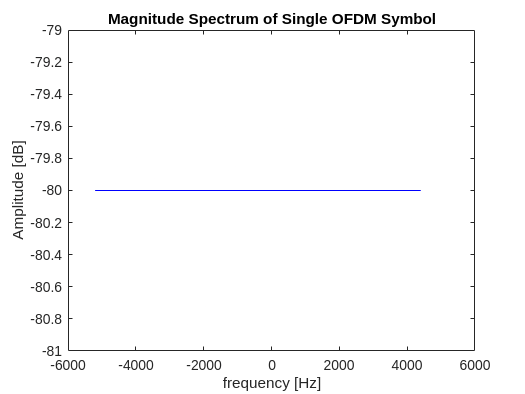


% plot the magnitude spectrum of the message
[f, spec] = GetSpectrum(t, s_t, OFDM_samplerate);
mag_spec = 20*log10(abs(spec));
figure(4)
clf
plot(f, mag_spec, 'b-')
title("Magnitude Spectrum of Single OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

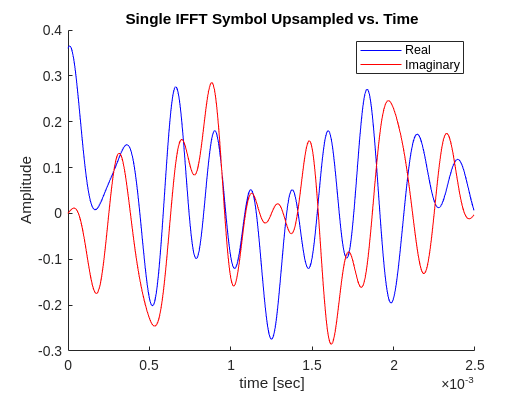


%% upsample the baseband message to see out of band distortion due to windowing
upsamp = 16;
OFDM_samplerate_resamp = OFDM_samplerate*upsamp;
OFDM_sampleperiod_resamp = OFDM_sampleperiod/upsamp;
s_t_resamp = resample(s_t,upsamp,1);
t_resamp = transpose((0:upsamp*num_bits-1)*OFDM_sampleperiod_resamp);


% plot the upsampled time domain message
figure(5)
clf
hold on
plot(t_resamp, real(s_t_resamp), 'b-')
plot(t_resamp, imag(s_t_resamp), 'r-')
hold off
title("Single IFFT Symbol Upsampled vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

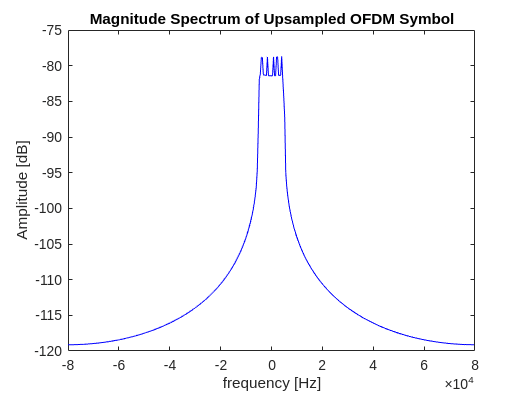


% plot the spectrum of the upsampled message
[f_resamp, spec_resamp] = GetSpectrum(t_resamp, s_t_resamp, OFDM_samplerate_resamp);
mag_spec_resamp = 20*log10(abs(spec_resamp));
figure(6)
clf
plot(f_resamp, mag_spec_resamp, 'b-')
title("Magnitude Spectrum of Upsampled OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

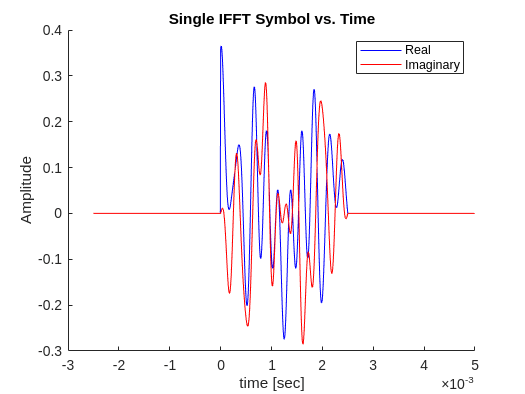


%% zero pad the upsampled message to show transition time distortion

% pad the time domain message with extra zeros (silent guard interval)
t_padded = transpose((-num_bits*upsamp:2*num_bits*upsamp-1)*OFDM_sampleperiod_resamp);
s_t_padded = zeros(3*num_bits*upsamp, 1, 'like', 1j);
s_t_padded(num_bits*upsamp+1:2*num_bits*upsamp) = s_t_resamp;

% plot the padded time domain message
figure(7)
clf
hold on
plot(t_padded, real(s_t_padded), 'b-')
plot(t_padded, imag(s_t_padded), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

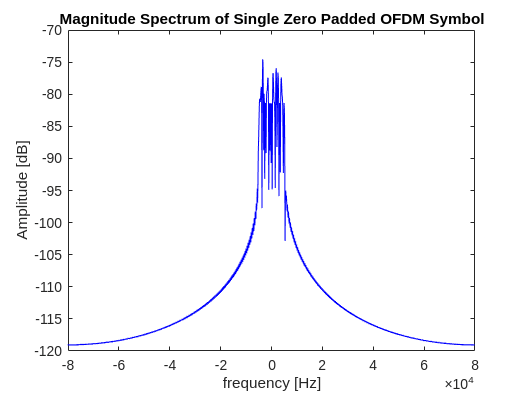


% find the spectrum of the original and padded message

[f_padded, spec_padded] = GetSpectrum(t_padded, s_t_padded, OFDM_samplerate_resamp);
mag_spec_padded = 20*log10(abs(spec_padded));

% plot the magnitude spectrum of the padded message
figure(8)
clf
plot(f_padded, mag_spec_padded, 'b-')
title("Magnitude Spectrum of Single Zero Padded OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")